% Load reconstructed_signal after being processed through Emd and wavlet
% based algorithm


reconstructed_signal=load('ECG_Data.txt')

reconstructed_signal =     0.2284
    0.2240
    0.2206
    0.2163
    0.2111
    0.2059
    0.1998
    0.1964
    0.1938
    0.1886


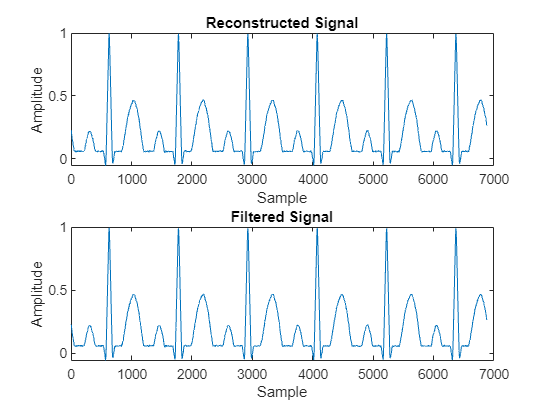

size_window = 5; 
threshold = 0.5; 

filtered_signal = zeros(size(reconstructed_signal));
signal_length = length(reconstructed_signal);


for i = 1:signal_length
    
    window_start = max(1, i - floor(size_window/2));
    window_end = min(signal_length, i + floor(size_window/2));
    new_window = reconstructed_signal(window_start:window_end);
    
    energy = sum(new_window.^2);
    if energy / (size_window + 1) < threshold
        
        filtered_signal(i) = reconstructed_signal(i);
    else
        
        filtered_signal(i) = mean(new_window);
    end
end


t = 1:signal_length;
figure;
subplot(2,1,1);
plot(t, reconstructed_signal);
title('Reconstructed Signal');
xlabel('Sample');
ylabel('Amplitude');

subplot(2,1,2);
plot(t, filtered_signal);
title('Filtered Signal');
xlabel('Sample');
ylabel('Amplitude');